t_start = 0;
t_end = 10;

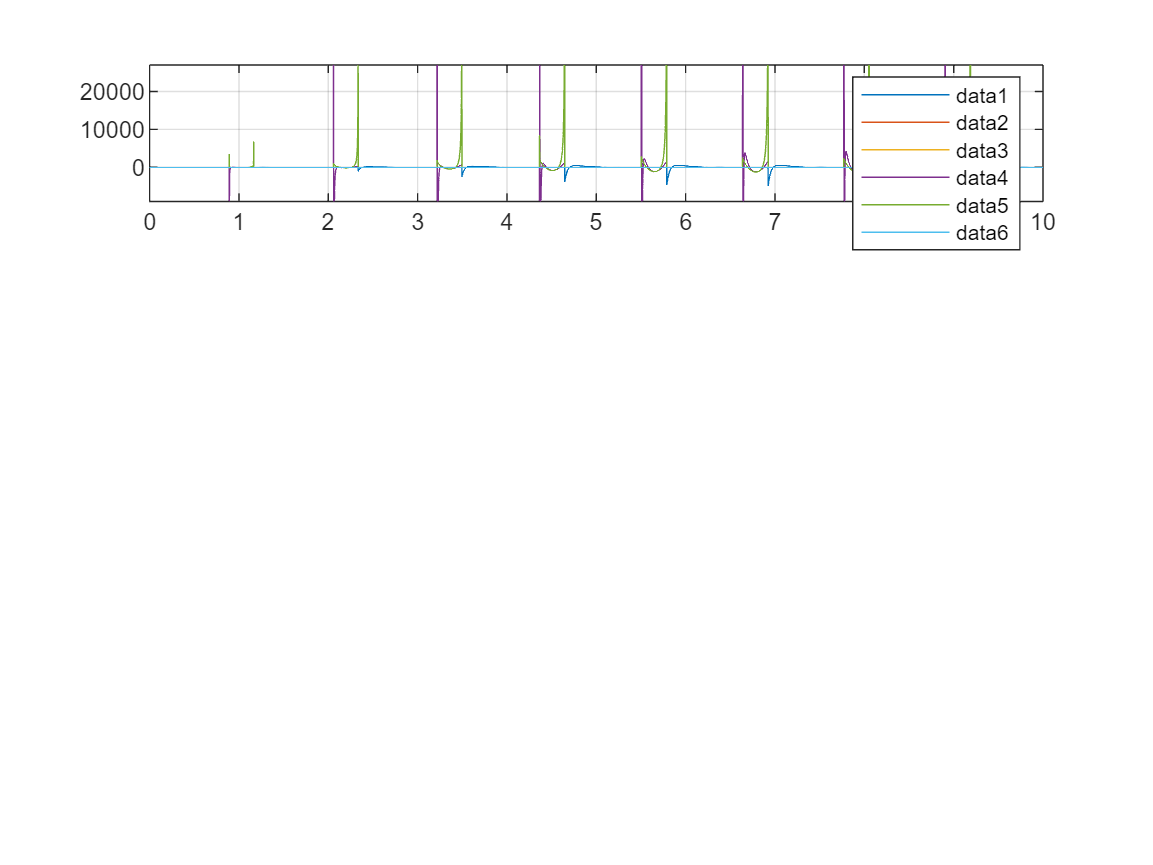

figure()
subplot(4,1,1)
plot(time, inputs)
hold on
plot(time, 10*flag(:,1))

legend
grid on

xlim([t_start,t_end])

## Single Stance Phase

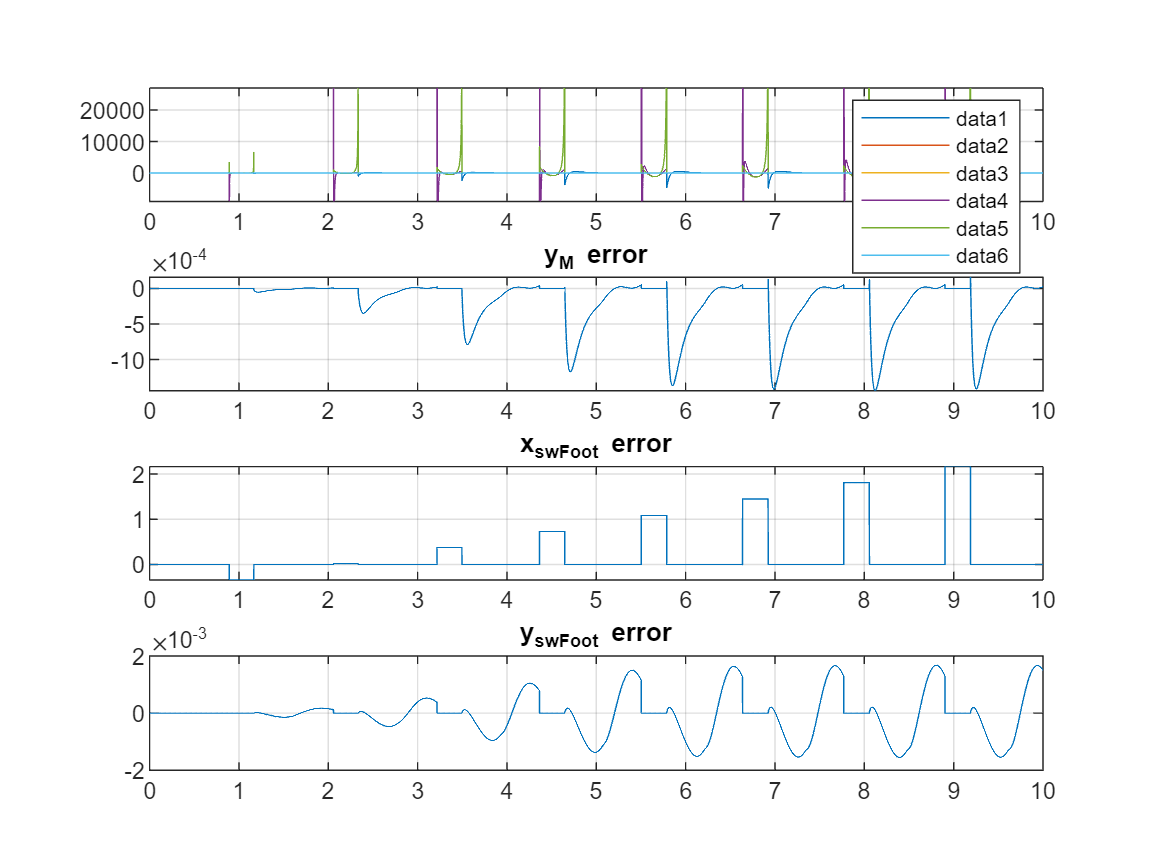

% ref_output_ss = [y_M_star; x_swFoot_star; y_swFoot_star]
y_M_ref = ref_output_ss(:,1);
x_sw_ref = flag(:,2) + ref_output_ss(:,2);
y_sw_ref = ref_output_ss(:,3);

% q = [x_M, y_M, theta, r, x_CoM y_CoM]
x_M = simout(:,1);
y_M = simout(:,2);
theta = simout(:,3);
r = simout(:,4);

x_swFoot = x_M + (r+L_thigh).*cos(theta);
y_swFoot = y_M + (r+L_thigh).*sin(theta);

% errors
y_M_error = y_M_ref - y_M;
x_swFoot_error = x_sw_ref - x_swFoot;
y_swFoot_error = y_sw_ref - y_swFoot;

errors_ss = [y_M_error, x_swFoot_error, y_swFoot_error];
error_titles_ss = [
    "y_M error"; "x_{swFoot} error"; "y_{swFoot} error"];
for i = 2:4
    subplot(4,1,i)
    plot(time(2:end), errors_ss(2:end, i-1))
    title(error_titles_ss(i-1))
    
    grid on
    xlim([t_start,t_end])
end

## Double Stance Phase

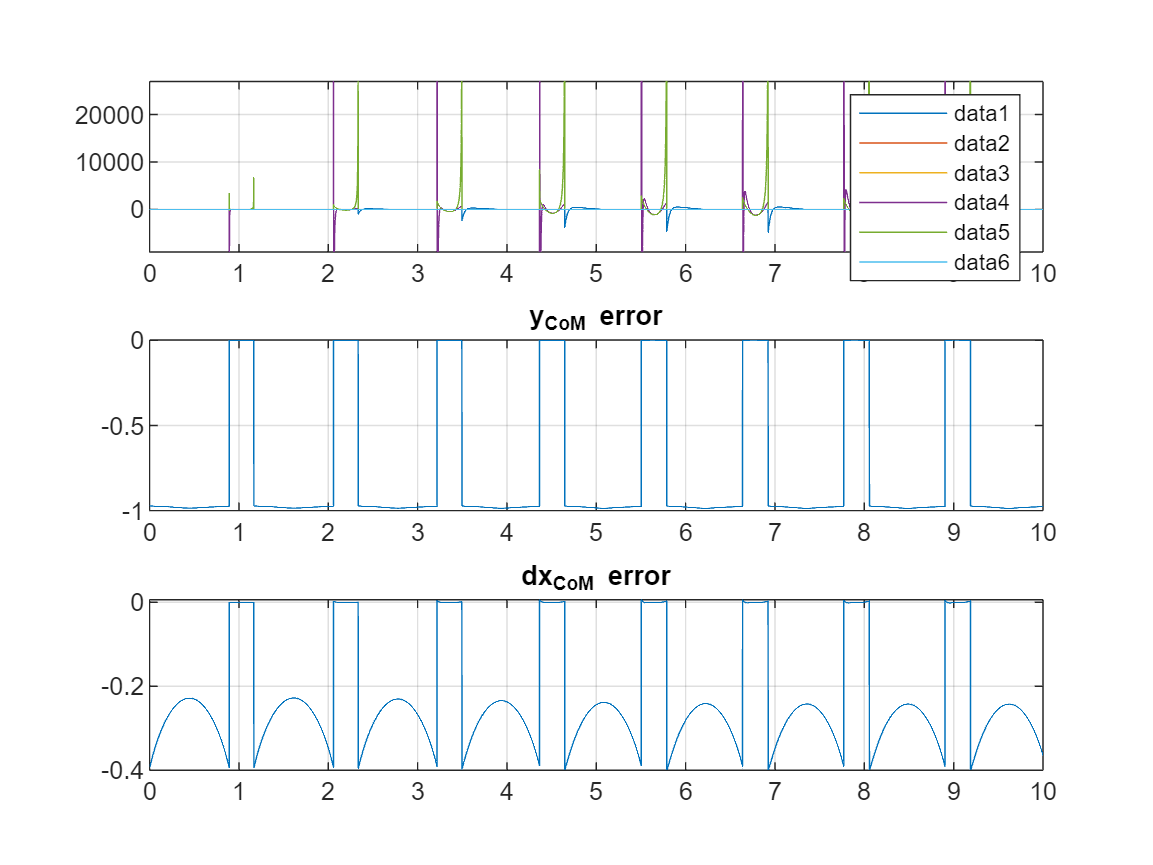

% ref_output_ds = [y_CoM_star; dx_CoM_star];
y_CoM_ref = ref_output_ds(:,1);
dx_CoM_ref = ref_output_ds(:,2);

% q = [x_M, y_M, theta, r, x_CoM y_CoM]
y_CoM = simout(:,6);
dx_CoM = simout(:,11);

% errors
y_CoM_error = y_CoM_ref - y_CoM;
dx_CoM_error = dx_CoM_ref - dx_CoM;

errors_ds = [y_CoM_error, dx_CoM_error];
error_titles_ds = [
    "y_{CoM} error"; "dx_{CoM} error"];

figure()
subplot(3,1,1)
plot(time, inputs)
hold on
plot(time, 10*flag(:,1))

legend
grid on

xlim([t_start,t_end])

for i = 2:3
    subplot(3,1,i)
    plot(time(2:end), errors_ds(2:end, i-1))
    title(error_titles_ds(i-1))
    
    grid on
    xlim([t_start,t_end])
end